# **CA#1 **

## **Name: Sogol Goodarzi **

## **SID: 810198467**

# **Part 5**

## **5.1)**

### ** For N=1**

### **Value and Phase of **$H\left(z\right)$:

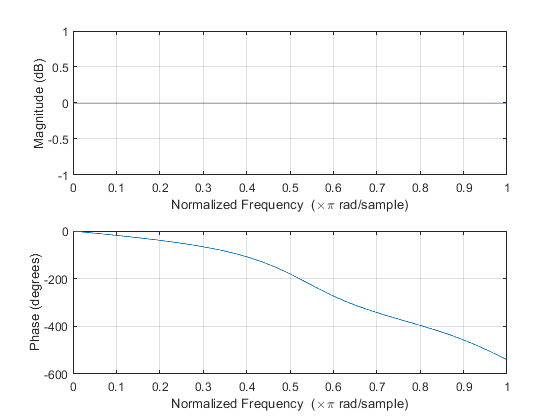

b=[1,2,3,4];
a=[4,3,2,1];
[h1,w]=freqz(b,a,1000);
freqz(b,a);

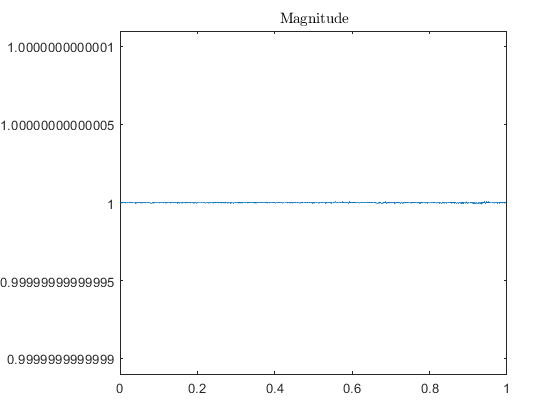

plot(w/pi,abs(h1));
title ('Magnitude','Interpreter','latex')

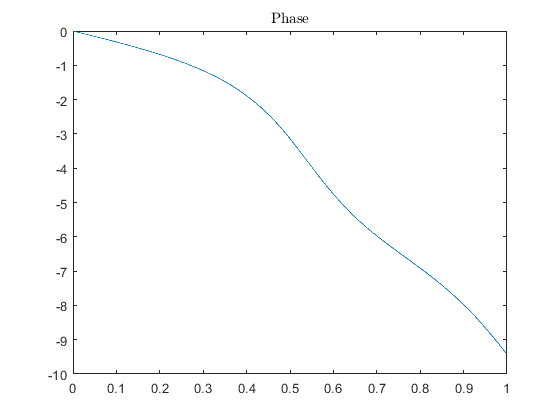

plot(w/pi,phase(h1));
title ('Phase','Interpreter','latex')

### Zeros and Poles :

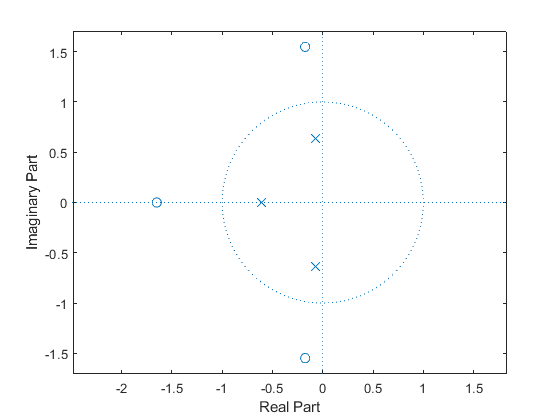

zplane(b,a);

## 5.2)

[y,Fs]=audioread('speech.wav');
y_filtered1=filter(b,a,y);
sound(y_filtered1,Fs)
audiowrite('output1.wav',y_filtered1,Fs);

## 5.3)

### ** For N=15**

### **Value and Phase of **$H\left(z\right)$:

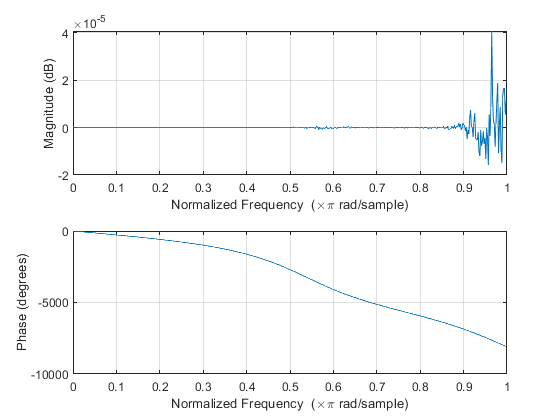

N=15;
b=[1,2,3,4];
a=[4,3,2,1];
A=1; B=1;
for i=1:N
    B=conv(B,b);
    A=conv(A,a);
end
[h2,w]=freqz(B,A,1000);
freqz(B,A);

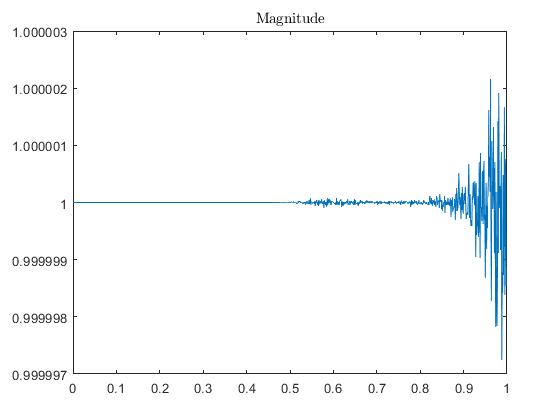

plot(w/pi,abs(h2));
title ('Magnitude','Interpreter','latex')

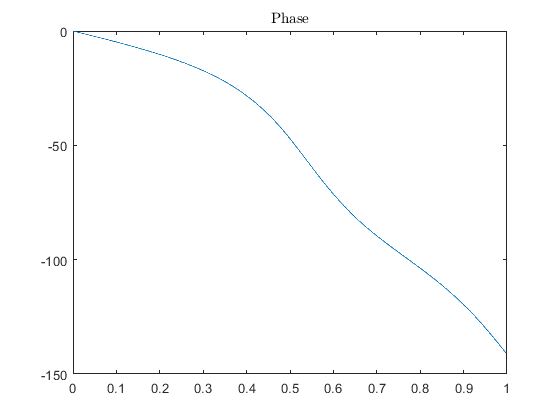

plot(w/pi,phase(h2));
title ('Phase','Interpreter','latex')

### Zeros and Poles :

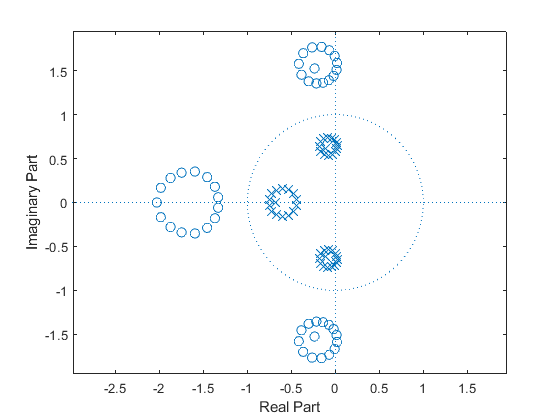

zplane(B,A);

## 5.4)

y_filtered2=filter(B,A,y);
sound(y_filtered2,Fs)
audiowrite('output2.wav',y_filtered2,Fs);

## 5.5)

### ** For N=50**

### **Value and Phase of **$H\left(z\right)$:

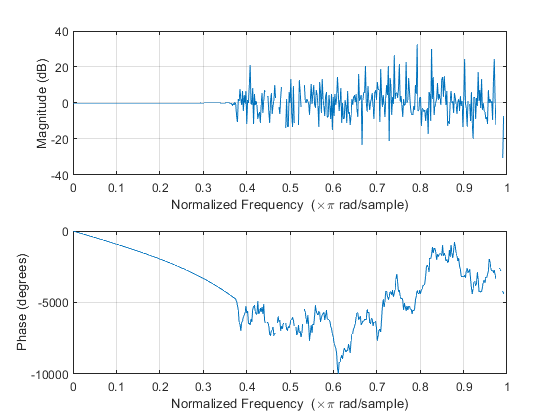

N=50;
b=[1,2,3,4];
a=[4,3,2,1];
A=1; B=1;
for i=1:N
    B=conv(B,b);
    A=conv(A,a);
end
[h3,w]=freqz(B,A,1000);
freqz(B,A);

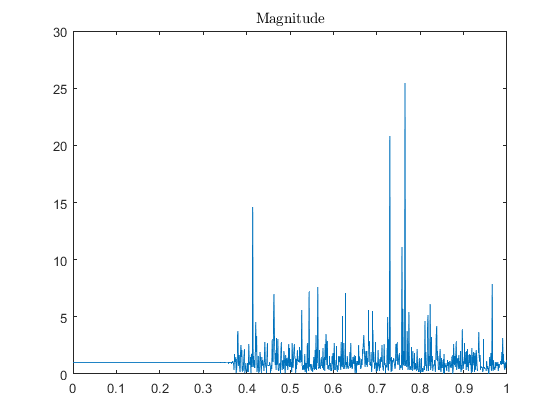

plot(w/pi,abs(h3));
title ('Magnitude','Interpreter','latex')

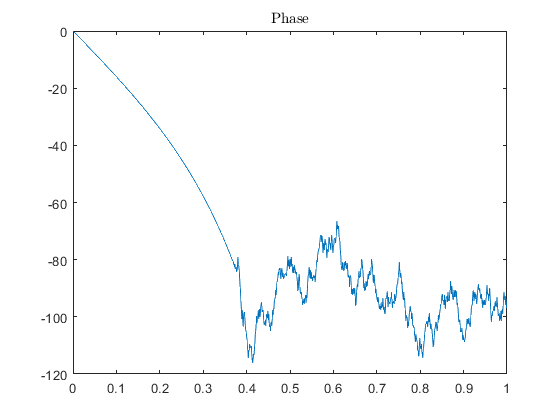

plot(w/pi,phase(h3));
title ('Phase','Interpreter','latex')

### Zeros and Poles :

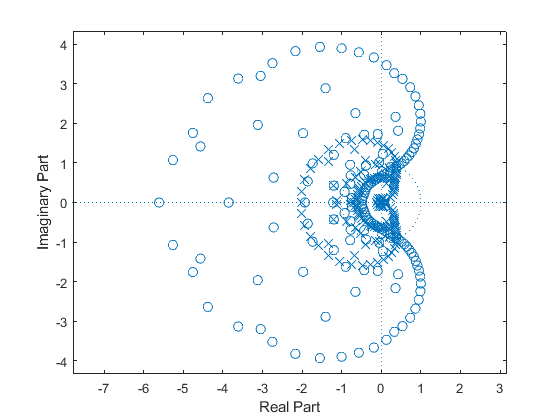

zplane(B,A);

y_filtered3=filter(B,A,y);
sound(y_filtered3,Fs)